# **Introductory script illustrating aspects of the TreeShrew optics**

*This script illustrates how to set different options in the threeshrew optics model, and how to produce and visualize optical images for optics models that differ in some parameter. This script also demonstrates that changing the spread of the PSF leads to changes in retinal image contrast and that changes in the focal length and/or the pupil size leads to changes in the retinal illuminance.*

**See also**: 

- `t_sceneForStimulusOnDisplay.mlx`

*Copyright: Nicolas P. Cottaris,  ISETBio Team,, 2018*

# **Step 1.** Generate different TreeShrew optics models 

### Step 1.1 Generate the default treeshrew optics

% Default tree shew optics
theDefaultOI = oiTreeShrewCreate('name', 'default optics');

% Lets see the default values of the treeshrew optics
defaultOpticsParams = opticsTreeShrewDefaultParams()

defaultOpticsParams = struct with fields:
                opticsType: 'gaussian psf'
    inFocusPSFsigmaMicrons: 6
             focalLengthMM: 4.3500
           pupilDiameterMM: 3


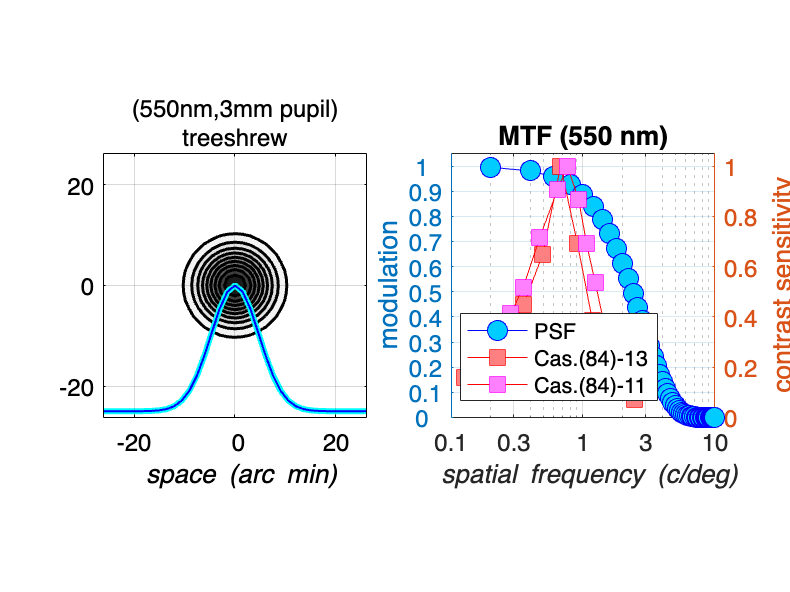


% Visualize the PSF at 550 nm
visualizedSpatialSupportArcMin = 50;
visualizedSpatialSfrequencyCPD = 10.0;
visualizeOpticsAtTargetWavelength(theDefaultOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData', csfTreeShrewFromPaper('casagrande84'));

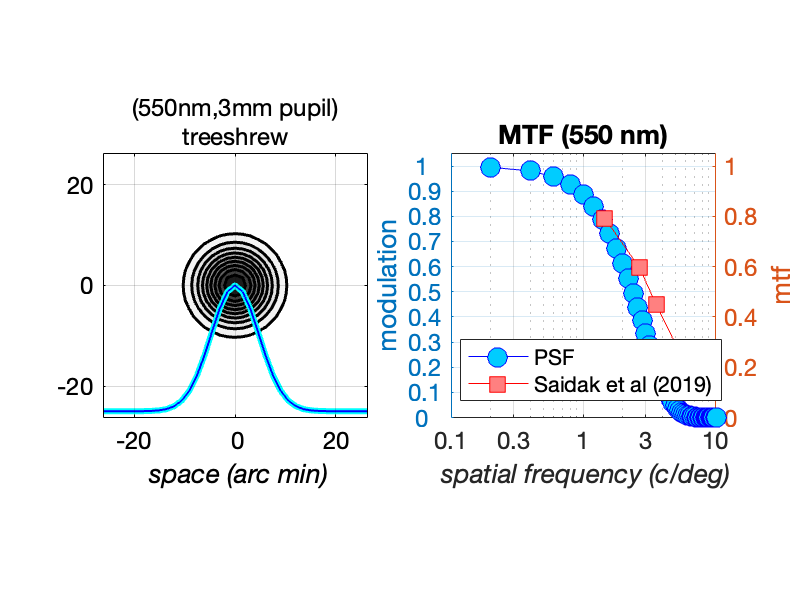


% Visualize the PSF at 550 nm
visualizeOpticsAtTargetWavelength(theDefaultOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData', mtfTreeShrewFromPaper('SaidakEtAl_2019'));

### **Step 1.2.** Generate custom TreeShrew optics - broad PSF (1.7 x default sigma)

Here we specify double the PSF spread. Note that this change broadens the PSF and as a results the MTF drops off faster with spatial frequency.

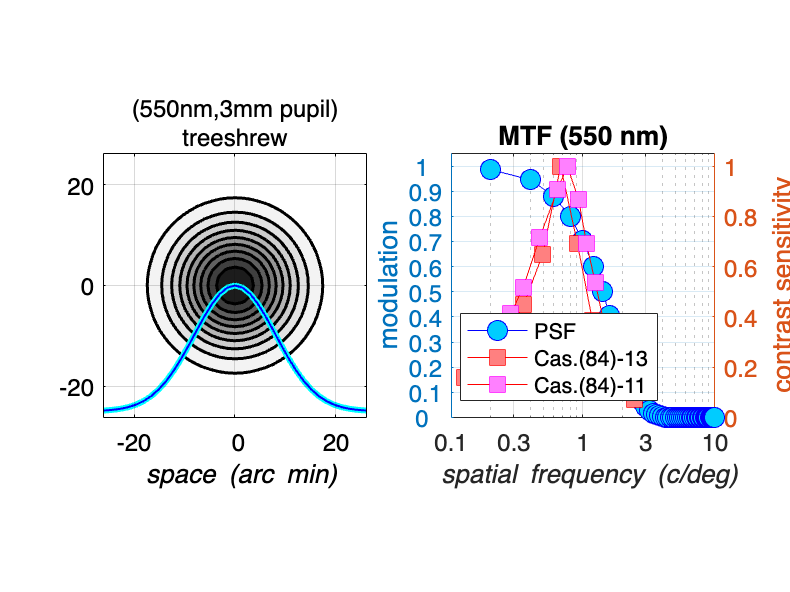

% Custom sigma tree shew optics 
theBlurredOI = oiTreeShrewCreate(...
    'name', 'blurry optics', ...
    'inFocusPSFsigmaMicrons', 1.7 * defaultOpticsParams.inFocusPSFsigmaMicrons ...
);

% Visualize the PSF/OTF at 550 nm
visualizeOpticsAtTargetWavelength(theBlurredOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData', csfTreeShrewFromPaper('casagrande84'))

### **Step 1.3 ** Generate custom TreeShrew optics - longer focal length (but same PSF spread in arc min)

Here we specify double the focal length  and double the PSF sigma, which is specified in retinal surface microns, so as to have the same PSF in arc min (same angular size).

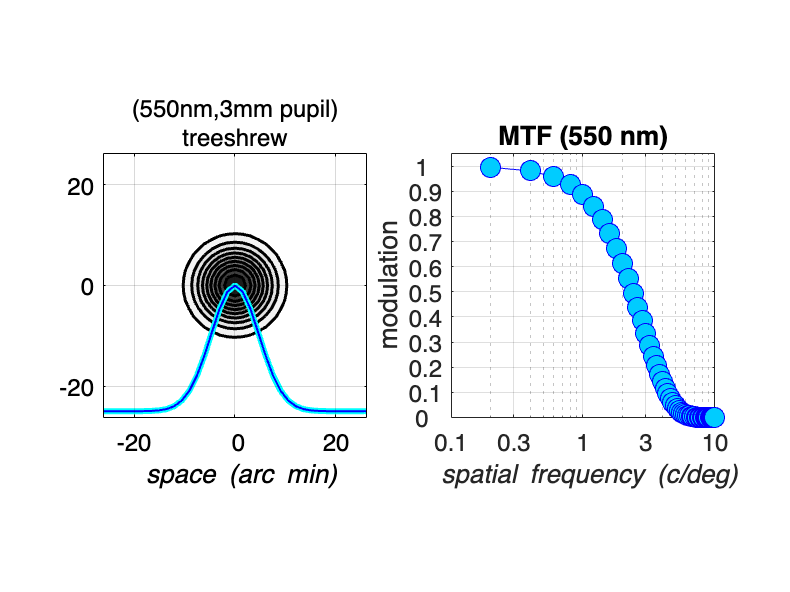

% Custom focal length tree shew optics
theLongerFocalLengthOI = oiTreeShrewCreate(...
    'name', 'longer focal length', ...
    'focalLengthMM', 2 * defaultOpticsParams.focalLengthMM, ... 
    'inFocusPSFsigmaMicrons', 2 * defaultOpticsParams.inFocusPSFsigmaMicrons ...
);
% Visualize the PSF/OTF at 550 nm
visualizeOpticsAtTargetWavelength(theLongerFocalLengthOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);

### **Step 1.4 .** Generate custom TreeShrew optics - longer focal length,  default PSF spread in arc min, and double the pupil size

Notice that changing the pupil size has no effect on the PSF. Note that in more realistic models, such as in wavefron-based optics, changes in pupil diameter results in changes in PSF spread.

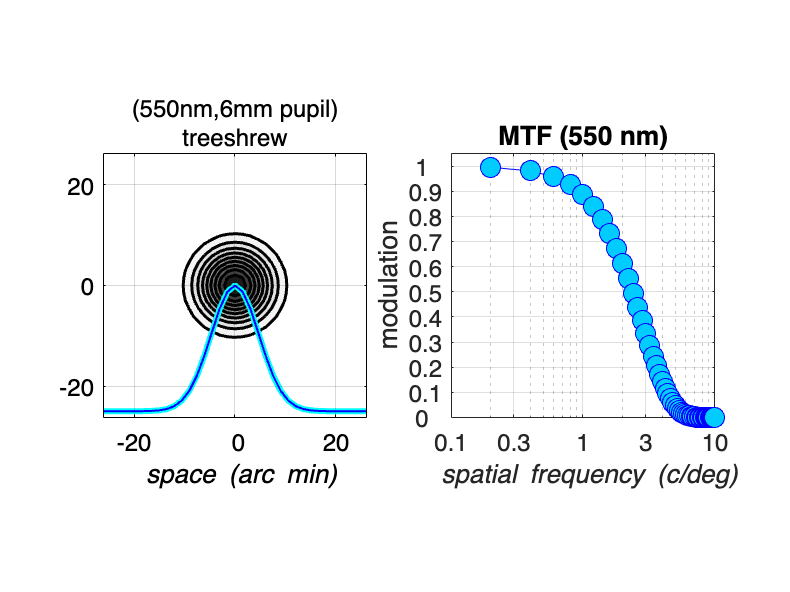

% Custom focal length tree shew optics, same PSF, double pupil size
opticsParams = opticsTreeShrewDefaultParams();
theLongerFocalLengthWidePupilOI = oiTreeShrewCreate(...
    'name', 'longer focal length, larger pupil', ...
    'focalLengthMM', 2 * defaultOpticsParams.focalLengthMM, ... 
    'inFocusPSFsigmaMicrons', 2 * defaultOpticsParams.inFocusPSFsigmaMicrons, ...
    'pupilDiameterMM', 2 * defaultOpticsParams.pupilDiameterMM ...
);

% Visualize the PSF/OTF at 550 nm
visualizeOpticsAtTargetWavelength(theLongerFocalLengthWidePupilOI, 550, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD);

# **Step 2.** Generate a test stimulus (1.0 c/deg Gabor) and rendered it on a typical display

We want to examine how different optics parameters affect the retinal image. To do this we need a test stimulus, a Gabor pattern generated below. 

### Step 2.1 Generate the test Gabor stimulus scene as it would be realized on a presentation display

%% Create presentation display and place it 5 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 5/100);

%% 1 c/deg Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 1.0, ... % 1.0 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 0, ...                    % spatial phase degrees
    'sizeDegs', 5.0, ...                    % 5 x 5 size
    'sigmaDegs', 0.7, ...                   % sigma of Gaussian envelope
    'contrast', 1.0,...                     % 100% Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );


% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay);

### Step 2.2 Visualize the stimulus scene

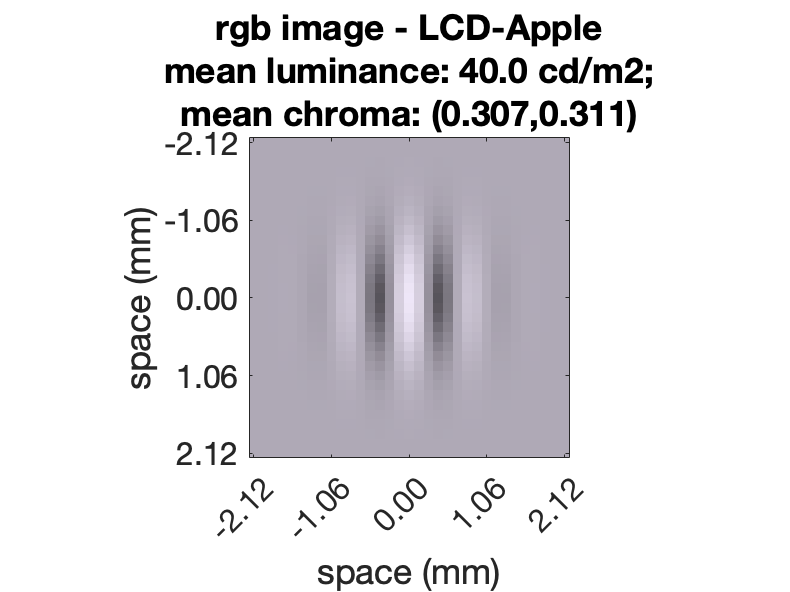

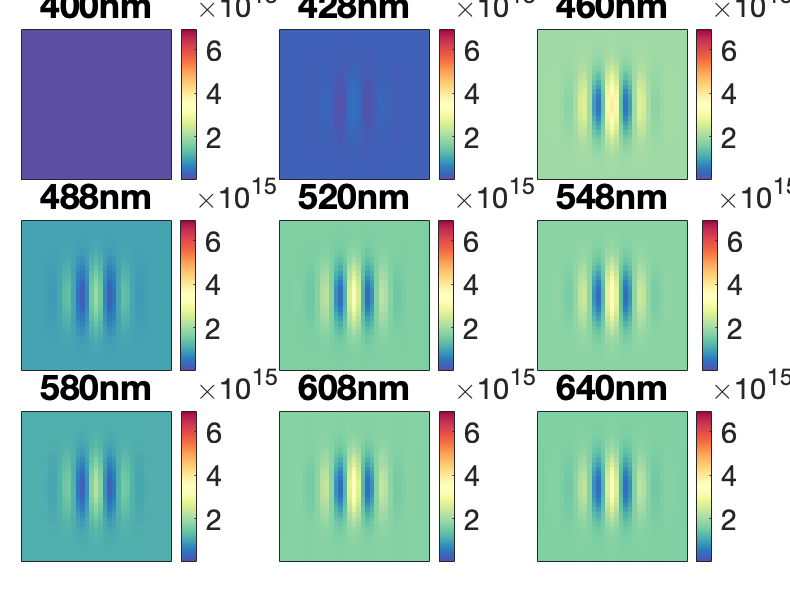

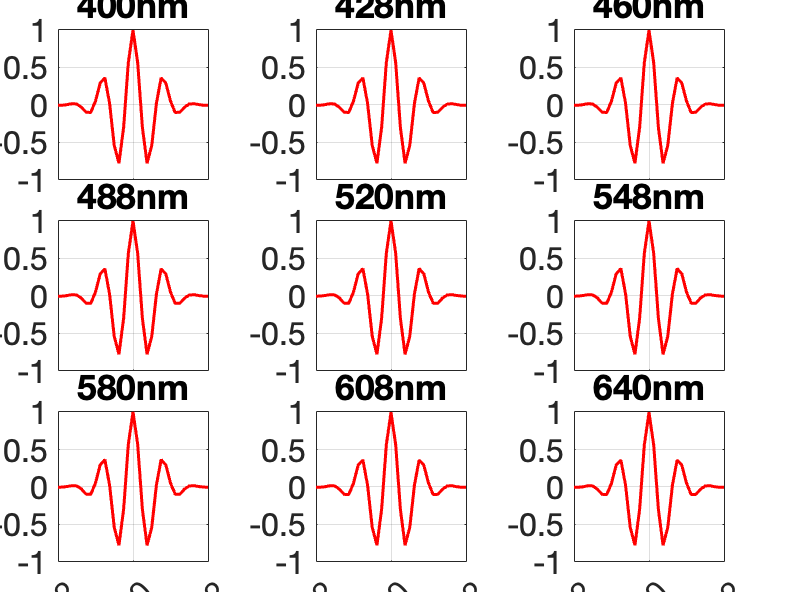

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene, 'displayContrastProfiles', true);

# **Step 3.** Generate retinal images for the different optics models

Below we compute the retinal images for our test scene using the different optics models we generated before.

### Step 3.1. Compute and visualize the retinal image for the default treeshrew optics model

Note that there is a mild reduction in retinal contrast for this 1.0 c/deg Gabor stimulus when the default optics are used.

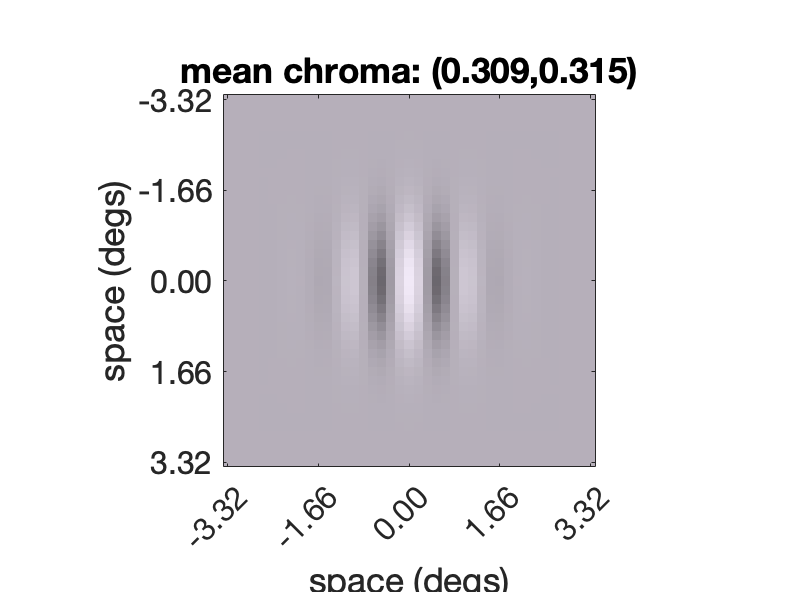

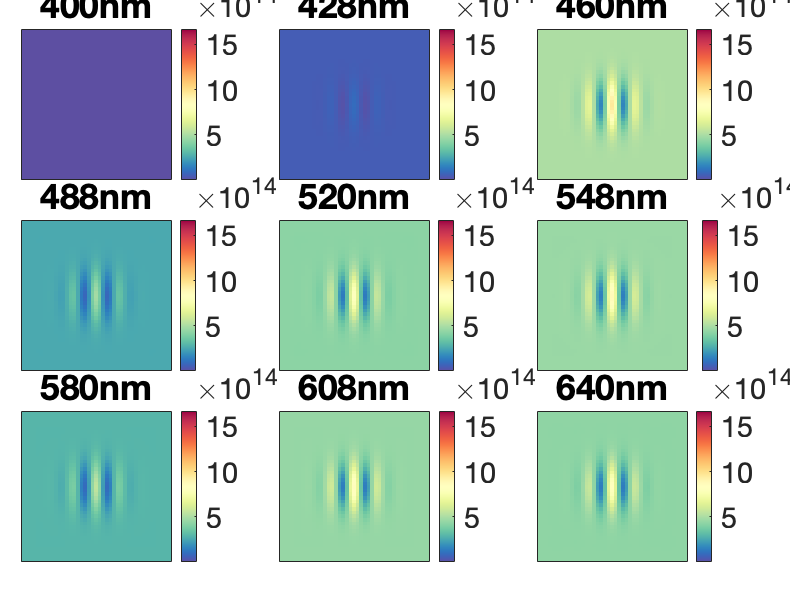

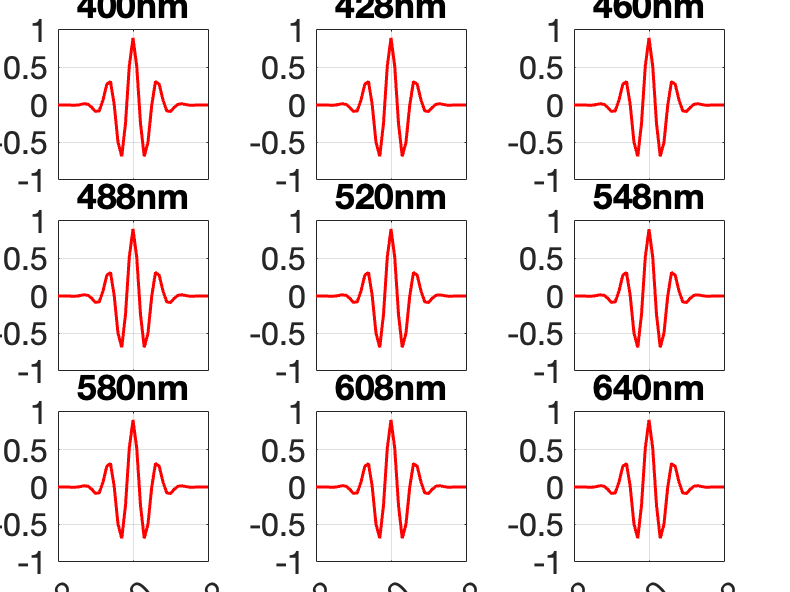

%% Compute the retinal image for the default optics
theDefaultOI = oiCompute(theDefaultOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theDefaultOI, 'displayRetinalContrastProfiles', true);


%% Retrieve the mean retinal illuminance
defaultOIMeanIlluminance = oiGet(theDefaultOI, 'mean illuminance')

defaultOIMeanIlluminance = 10.3650

### Step 3.2. Compute and visualize the retinal image for the blurry optics (large PSF)

With the blurry optics, there is a 50% reduction in retinal cone contrast for this 1 c/deg Gabor stimulus. The mean retinal illuminance however is identical to that under the default optics.

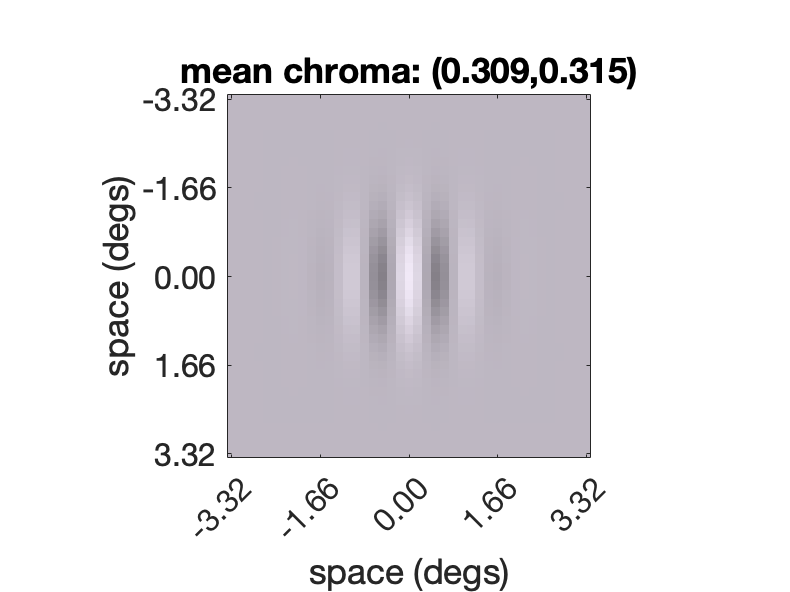

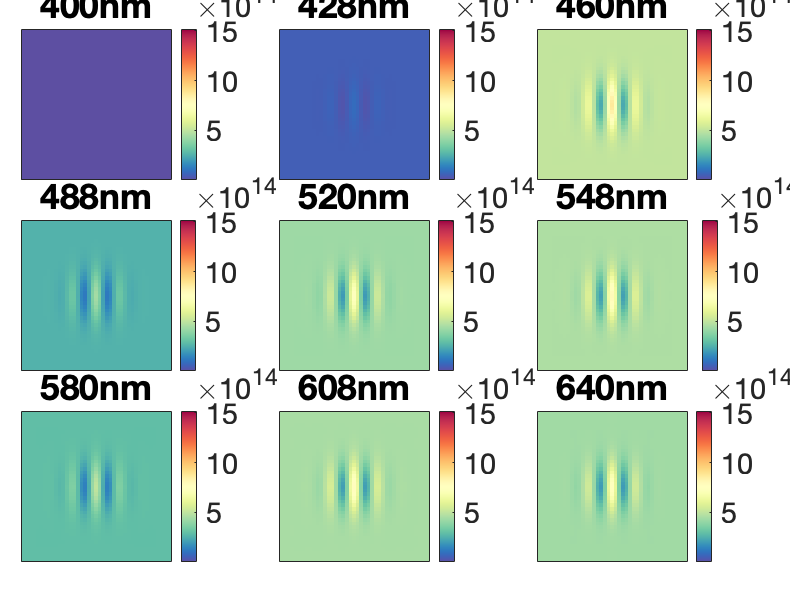

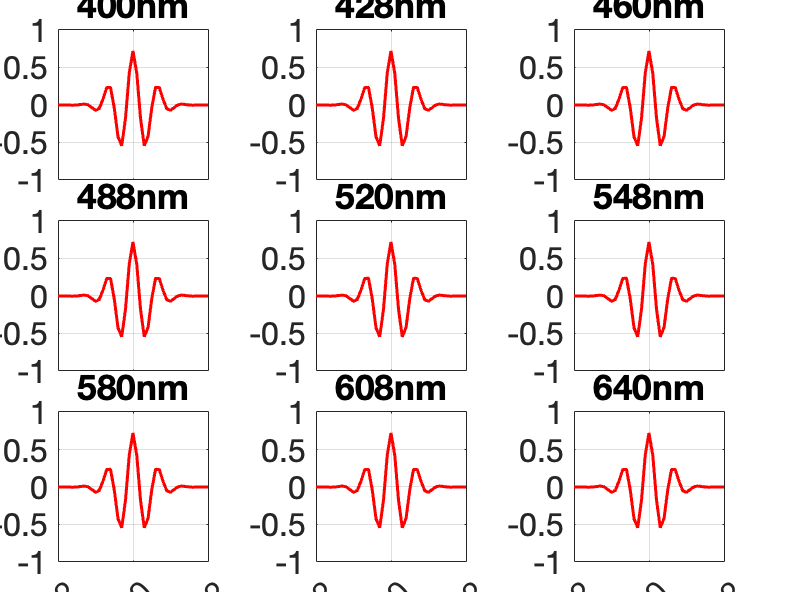

%% Compute the retinal image for the blurred optics
theBlurredOI = oiCompute(theBlurredOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theBlurredOI, 'displayRetinalContrastProfiles', true);


%% Retrieve the mean retinal illuminance
blurredOIMeanIlluminance = oiGet(theBlurredOI, 'mean illuminance')

blurredOIMeanIlluminance = 10.3650

illuminanceRatio = (blurredOIMeanIlluminance-defaultOIMeanIlluminance)/defaultOIMeanIlluminance

illuminanceRatio = -2.7980e-10

### Step 3.3. Compute and visualize the retinal image for the longer focal length optics

Note that the retinal contrast slices obtained using these optics are identical to those obtained under the blurry optics. So changing the focal length, with corresponding changes in the PSF so that the angular size of the PSF remains constant, does not affect the retinal cone contrast. This change in focal length however, does have a major impact on the retinal illuminance. Doubling the focal length, reduces the mean retinal illuminance to 23% of that in the default optics (25% = 0.5^2 is the theoretical value)

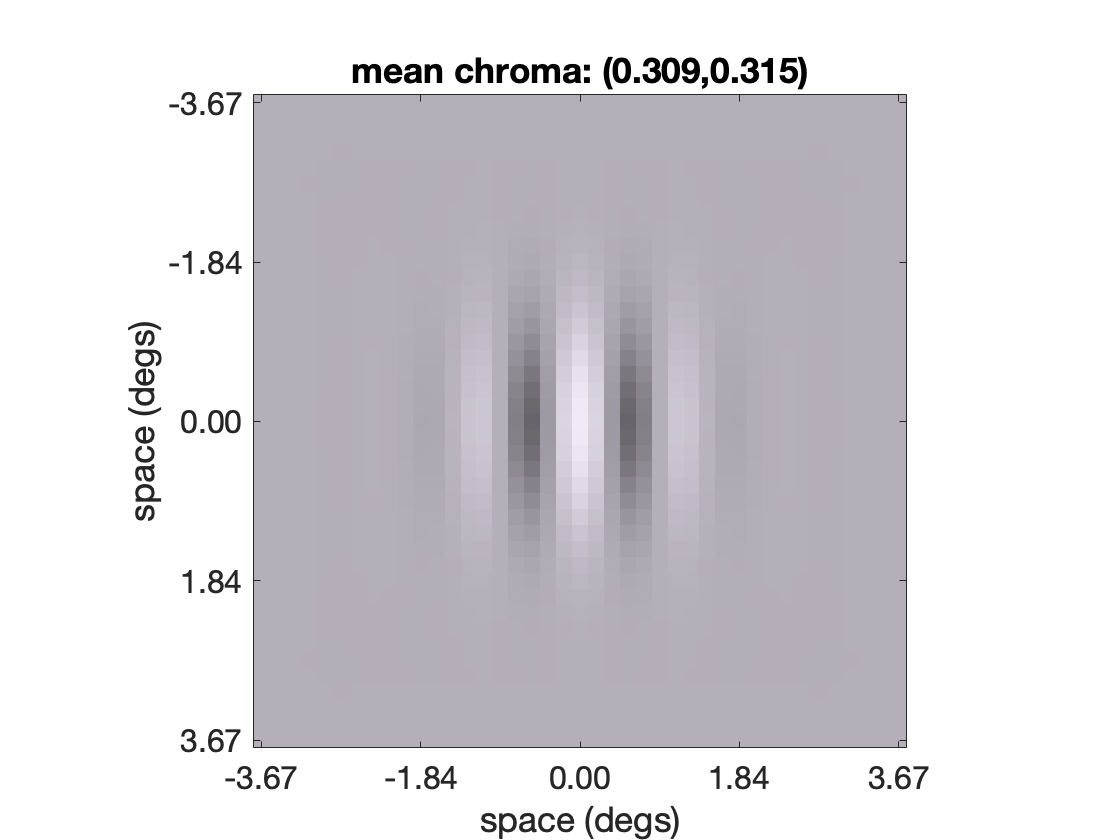

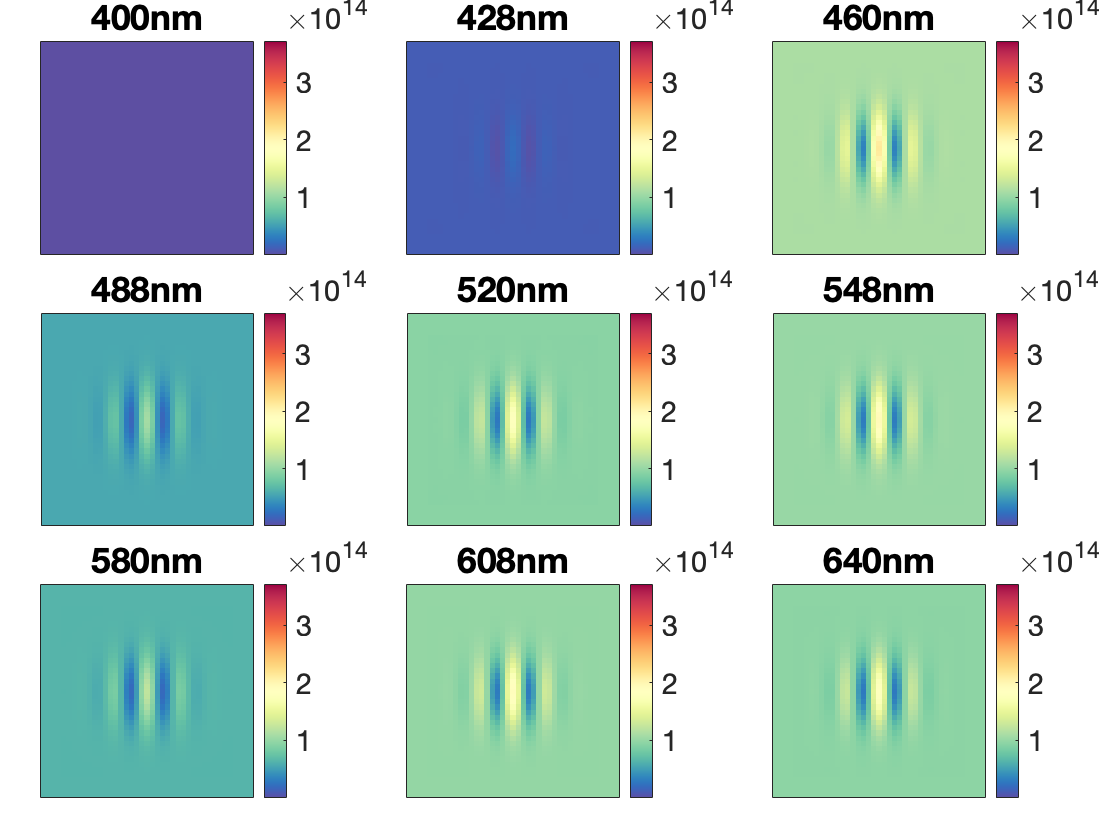

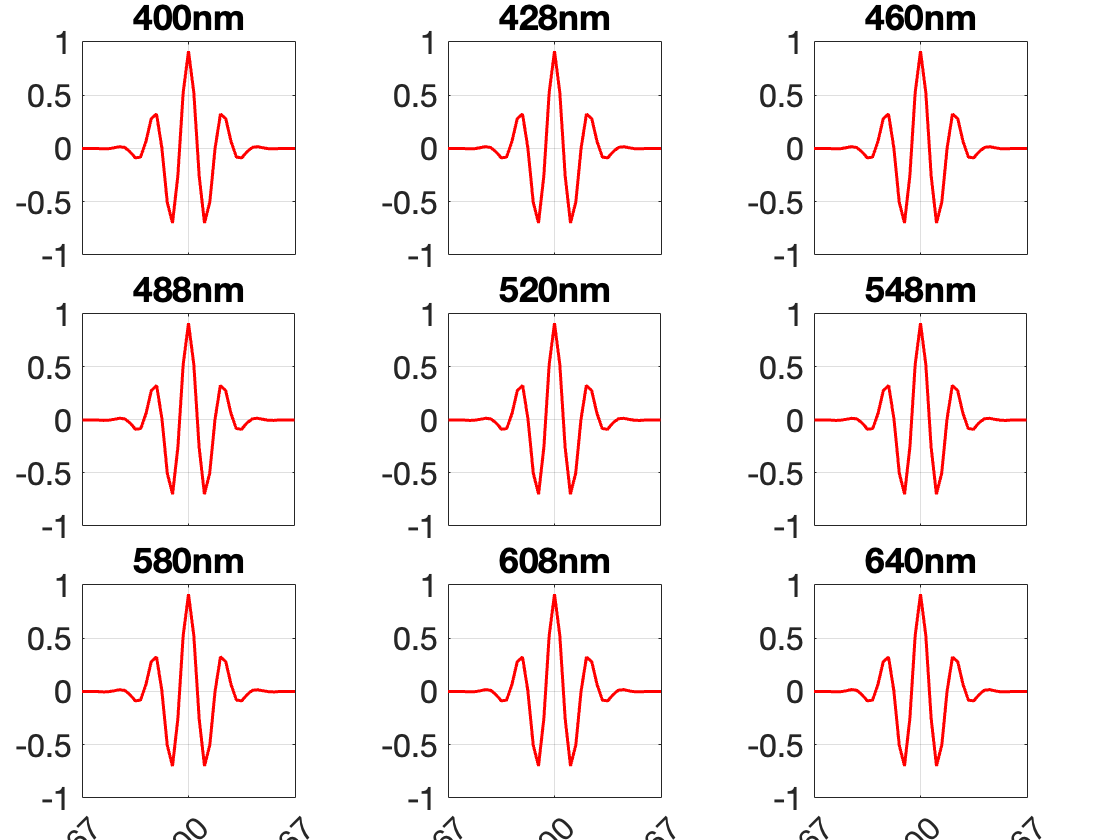

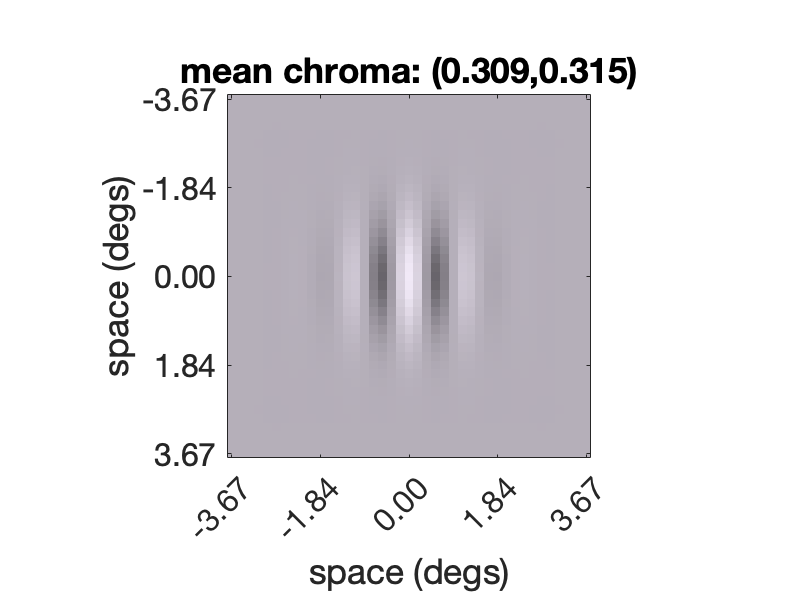

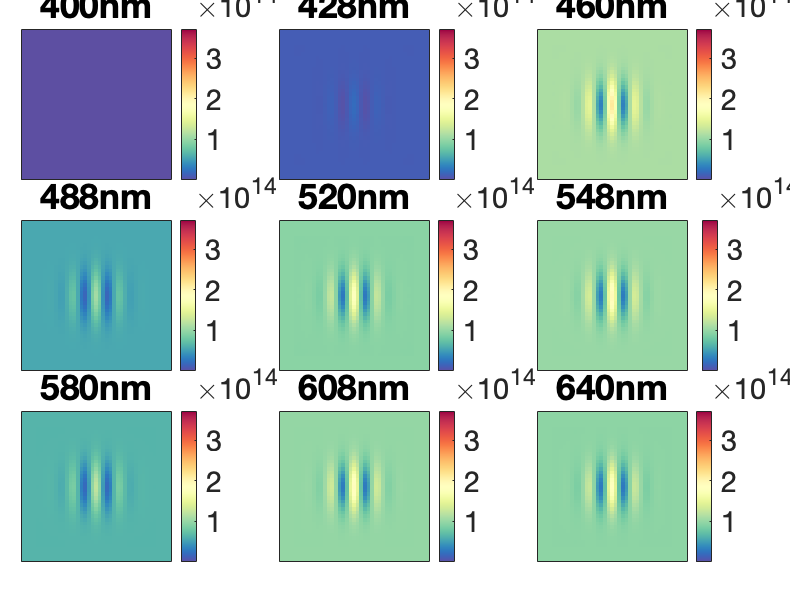

%% Compute the retinal image for the longer focal length optics
theLongerFocalLengthOI = oiCompute(theLongerFocalLengthOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theLongerFocalLengthOI, 'displayRetinalContrastProfiles', true);


%% Retrieve the mean retinal illuminance
longerFocalLengthOIMeanIlluminance = oiGet(theLongerFocalLengthOI, 'mean illuminance')

longerFocalLengthOIMeanIlluminance = 2.2831

illuminanceRatio = longerFocalLengthOIMeanIlluminance/defaultOIMeanIlluminance

illuminanceRatio = 0.2203

### Step 3.4. Compute and visualize the retinal image for the longer focal length optics with wide pupil

Here we see that doubling the pupil diameter has no effect on retinal contrast, as the angular PSF is unchanged. It does however, counteract the reduction in retinal illuminance induced by doubling of the focal length and brings retinal illuminance near (84%) that of the default optics. Not sure why it is not much closer though.

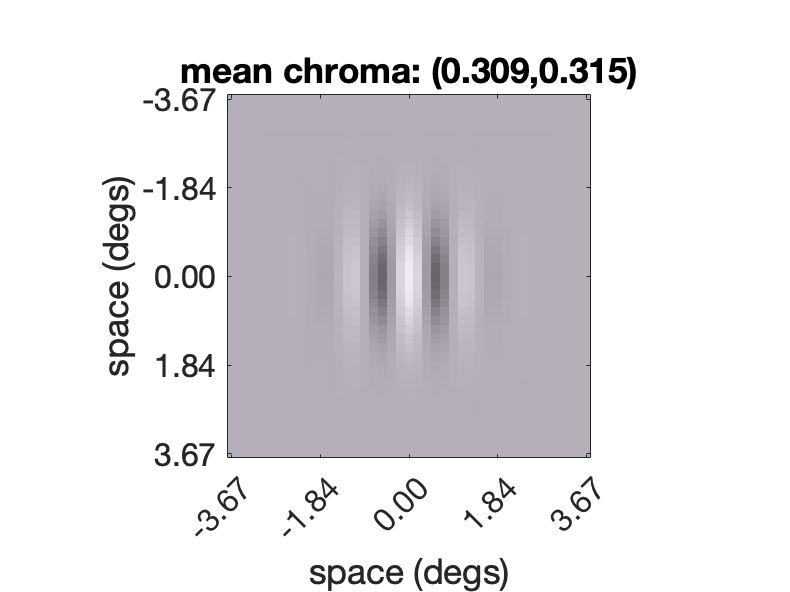

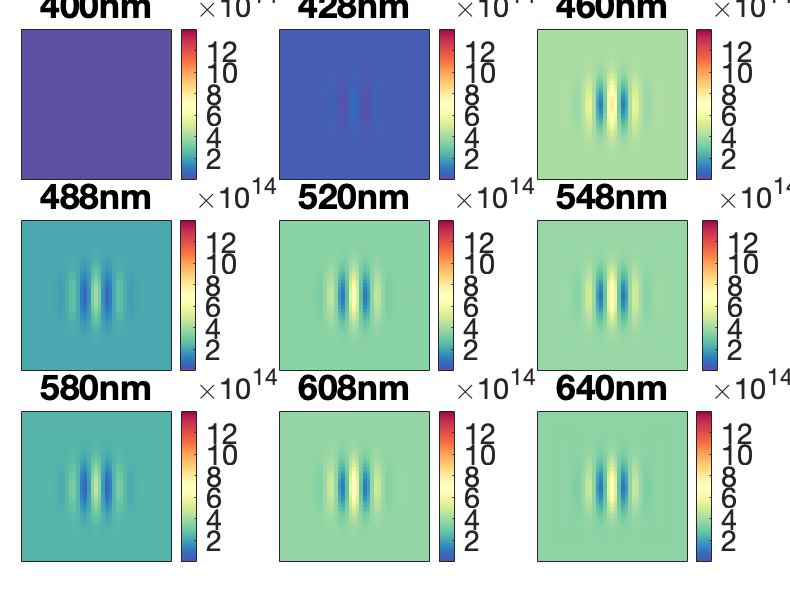

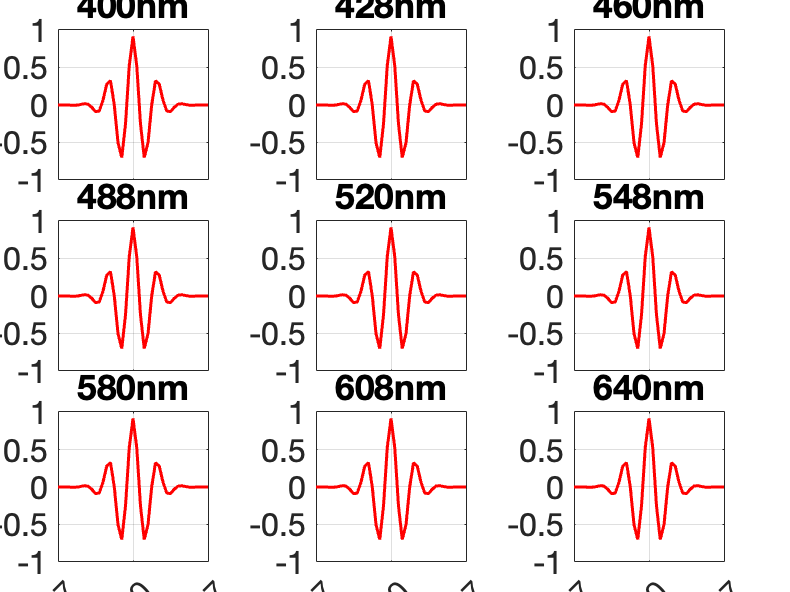

%% Compute the retinal image for the longer focal length, wider pupil optics
theLongerFocalLengthWidePupilOI = oiCompute(theLongerFocalLengthWidePupilOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theLongerFocalLengthWidePupilOI, 'displayRetinalContrastProfiles', true);


%% Retrieve the mean retinal illuminance
longerFocalLengthWidePupilOIMeanIlluminance = oiGet(theLongerFocalLengthWidePupilOI, 'mean illuminance')

longerFocalLengthWidePupilOIMeanIlluminance = 8.6192

illuminanceChange = longerFocalLengthWidePupilOIMeanIlluminance/defaultOIMeanIlluminance

illuminanceChange = 0.8316